## Esercizio sull'analisi delle corrispondenze

% La zona A1:B1037 del file soft-drinks.xlsx contiene i risultati di un'indagine in cui si è chiesto
% di associare ad ogni brand nel mercato delle "soft drinks" una determinata parola.
% 
% 1) Costruire la distribuzione di frequenza della variabile Marca.
% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Aggiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA
% 
% 2) Costruire la tabella di contingenza tra le due variabili (Variabile Parola sulle righe).
% 
% 3) Costruire manualmente la tabella delle frequenze teoriche e calcolare
% manualmente l'indice Chi2 ed il relativo p-value. Denominare la variabile
% che contiene la table delle frequenze teoriche comprensiva delle intestazioni di riga e
% di colonna Ntable
%
% 4) Analizzare l'entità dell'associazione tramite l'indce di Cramer.
% Commentare l'indice. Denominare la variabile che contiene l'indice di
% Cramer CRA
% 
% 5) Costruire e commentare il grafico di analisi delle corrispondenze.  
% Commentare la quota di inerzia spiegata e le relazioni tra i punti riga ed i punti colonna. 
% 
% 6) Discutere i due punti riga più dominanti nella spiegazione
% dell'inerzia della prima dimensione latente.
%
% 7) Costruire e commentare il moonplot
%
% 8) Utilizzando la funzione CorAnaplot, ripetere il grafico di analisi
% delle corrispodenza adottando una mappa di colore.
% Nel primo grafico le etichette di riga devono avere un colore che dipende dalla loro
% massa.
% Nel secondo grafico le etichette di riga devono avere un colore che dipende
% dal contributo dei punti riga all'inerzia delle prime due dimensioni
% latenti 
% Suggerimento: utilizzando l'opzione plots di CorAnaplot.

close all
clear
X = readtable('soft-drinks.xlsx','Sheet','Foglio1','range','A1:B1037');

% 1) Costruire la distribuzione di frequenza della variabile Marca.
% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Agiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA

% Distribuione di frequenza della variabile Marca
Xca=categorical(X.Marca);
disp('Distribuzione di frequenze della variabile marca')

Distribuzione di frequenze della variabile marca


summary(Xca);

     Coke          332 
     DietCoke       45 
     Fanta         126 
     Pepsi          69 
     RedBull       213 
     V             251 


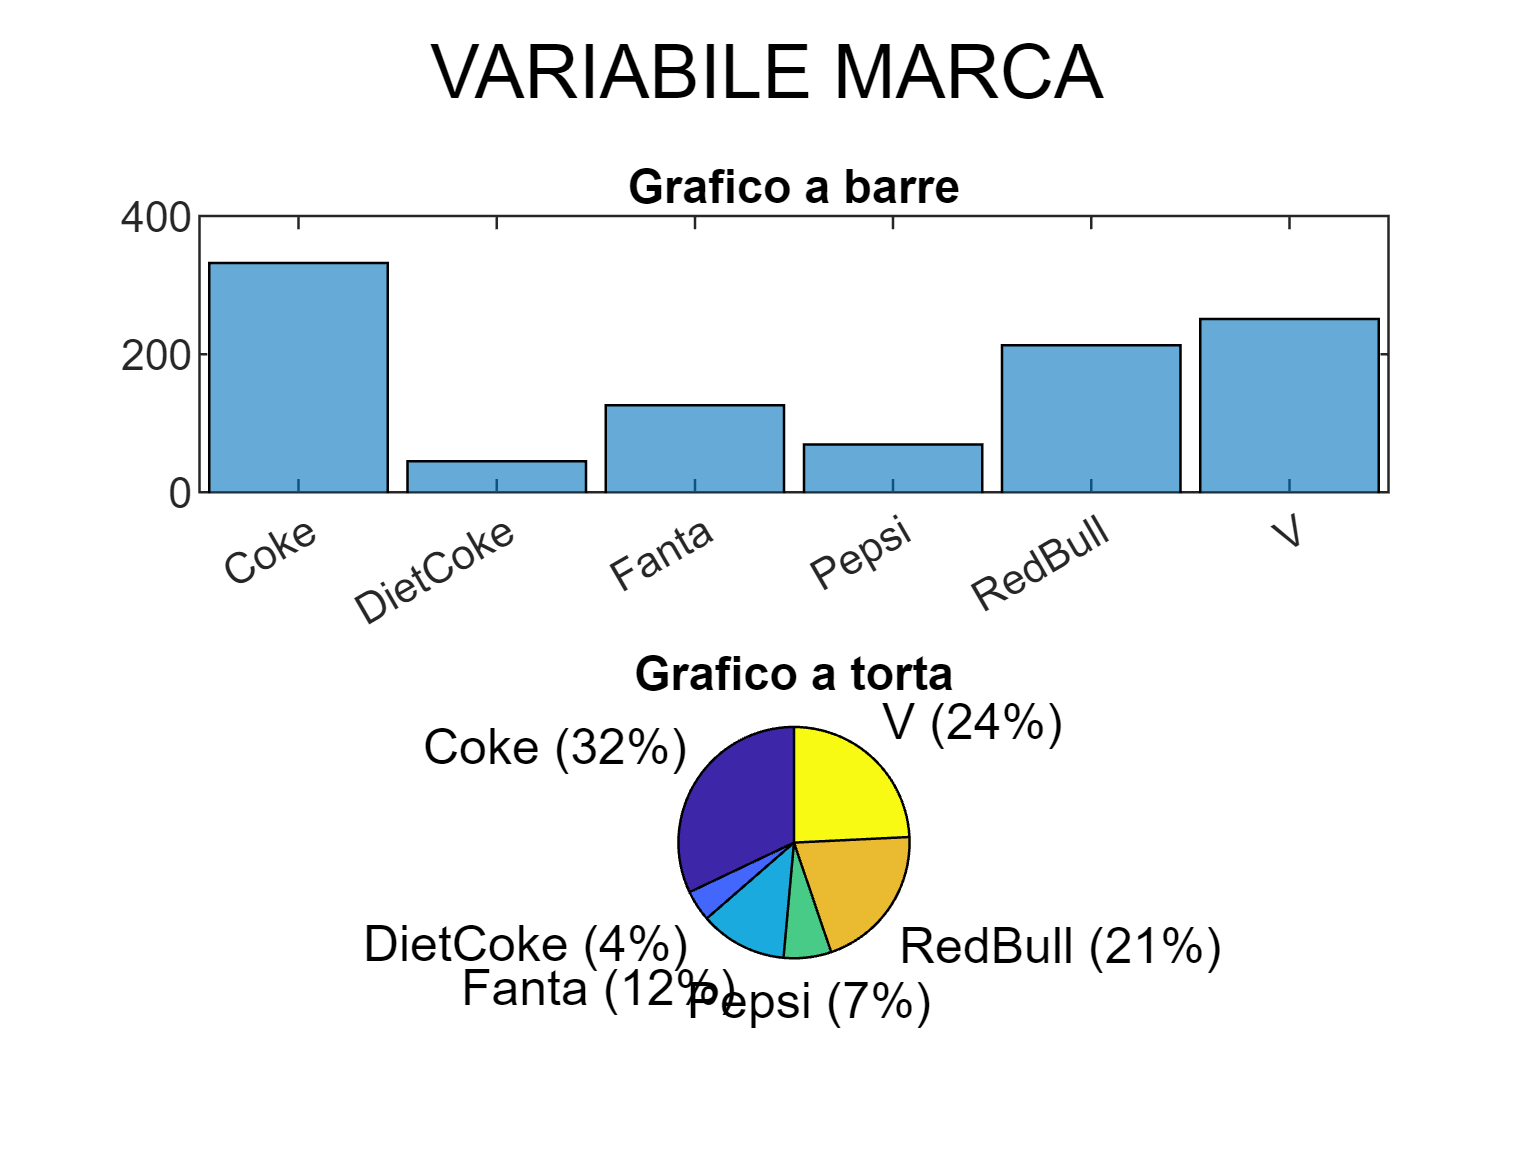


% Osservazione: andava bene anche 
% tabulate(X.Marca)

% Rappresentare graficamente tramite grafico a barre e grafico a torta la
% distribuzione di frequenza in percentuale in due pannelli orizzontali. 
% Aggiungere il titolo del grafico ad entrambi i pannelli.
% Inserire come titolo complessivo dei due pannelli
% VARIABILE MARCA

subplot(2,1,1)
% Grafico a barre
histogram(Xca);  
title('Grafico a barre');
% Grafico a torta
subplot(2,1,2)
pie(Xca); % GRAFICO A TORTA
title('Grafico a torta');
sgtitle('VARIABILE MARCA')


% Commento: Coke, V e RedBull sono le tre marche più frequenti

% 2) Costruire la tabella di contingenza tra le due variabili (Variabile Parola sulle righe).

% Tabella di contingenza
[N,chi2CHK,pvalCHK,labels] =crosstab(X.Parola,X.Marca);
% chi2CHK e pvalCHK sono rispettivamente il valore dell'indice chi quadrato
% ed il p-value da confrontare con l'implementazione manuale.
[I,J]=size(N);

% 3) Costruire manualmente la tabella delle frequenze teoriche e calcolare
% manualmente l'indice Chi2 ed il relativo p-value. Denominare la variabile
% che contiene la table delle frequenze teoriche comprensiva delle intestazioni di riga e
% di colonna Ntable

% Costruzione della tabella di contingenza in formato table
% Dall'array N alla tabella Ntable
Ntable=array2table(N,'RowNames',labels(1:I,1),'VariableNames',labels(1:J,2));
disp('Tabella di contingenza tra Parola e Marca')

Tabella di contingenza tra Parola e Marca


disp(Ntable)

                   Coke       V      RedBull    Fanta    Pepsi    DietCoke
                   _____    _____    _______    _____    _____    ________

    Teens          69.00    46.00     41.00     13.00    22.00     18.00  
    PicksYouUp     29.00    52.00     45.00      3.00     5.00      3.00  
    Energy         19.00    55.00     47.00      2.00     3.00      1.00  
    EnjoyLife      50.00    22.00     19.00      8.00    10.00      7.00  
    WhenTired      25.00    38.00     33.00      2.00     4.00      3.00  
    Kids           30.00     2.00      1.00     45.00     8.00      2.00  
    Fun            35.00     6.00      5.00     32.00     5.00      2.00  
 


% 3) Costruire manualmente la tabella delle frequenze teoriche e calcolare
% manualmente l'indice Chi2 ed il relativo p-value. Denominare la variabile
% che contiene la table delle frequenze teoriche comprensiva delle intestazioni di riga e
% di colonna Ntable
%

%% Calcolo della tabella delle frequenze teoriche 

% n= numero di unità del campione
n=sum(sum(N));
sumc=sum(N,1);
sumr=sum(N,2);
Ntheo=(sumr*sumc/n);
rownam=labels(1:I,1);
NtheoT=array2table(Ntheo,'RowNames',rownam,'VariableNames',labels(1:J,2));
disp('Tabella delle frequenze teoriche nel caso di indipendenza')

Tabella delle frequenze teoriche nel caso di indipendenza


disp(NtheoT)

                   Coke       V      RedBull    Fanta    Pepsi    DietCoke
                   _____    _____    _______    _____    _____    ________

    Teens          66.98    50.64     42.97     25.42    13.92      9.08  
    PicksYouUp     43.90    33.19     28.17     16.66     9.12      5.95  
    Energy         40.70    30.77     26.11     15.45     8.46      5.52  
    EnjoyLife      37.17    28.10     23.85     14.11     7.73      5.04  
    WhenTired      33.65    25.44     21.59     12.77     6.99      4.56  
    Kids           28.20    21.32     18.09     10.70     5.86      3.82  
    Fun            27.24    20.59     17.48     10.34     5.66      3.69  
 


%% Calcolo in maniera manuale indice Chi2 e p value
Chi2=sum(((N-Ntheo).^2)./Ntheo,'all');
disp(['Indice Chi2:' num2str(Chi2)])

Indice Chi2:396.628


disp('Controllo uguaglianza sulle due implementazioni indice Chi2')

Controllo uguaglianza sulle due implementazioni indice Chi2


disp(isequal(Chi2,chi2CHK));

   1



% Calcolo p value del test = probabilità di ottenere un valore supereriore
% a Chi3 nella v.c. chi quadrato con (I-1)*(J-1) ossia 45 gradi di libertà
gdl=(I-1)*(J-1);
pval=chi2cdf(Chi2,gdl,'upper');
disp('differenze tra le due implementazioni del p-value')

differenze tra le due implementazioni del p-value


disp(pval-pvalCHK);

             0



% p value vitualmente uguale a zero===> forte associazione tra le variabili "parola" e
% "marca". Rifiutiamo sicuramente l'ipotesi nulla di indipendenza tra le due
% variabili ==> Ogni brand è associato ad una o più parole. L'obiettivo
% dell'analisi delle corrispondenze è capire quali parole sono associate a
% quali marchi.

% 4) Analizzare l'entità dell'associazione tramite l'indce di Cramer.
% Commentare l'indice. Denominare la variabile che contiene l'indice di
% Cramer CRA

%% calcolo indice Cramer tramite la funzione corrNominal
out=corrNominal(N);

Chi2 index
        396.63

pvalue Chi2 index
          0.00

Phi index
          0.62

Cramer's V 
          0.28

Test of H_0: independence between rows and columns
                  Coeff     se     zscore    pval
                  _____    ____    ______    ____

    CramerV       0.28     0.02    12.34     0.00
    GKlambdayx    0.12     0.02     5.43     0.00
    tauyx         0.08     0.01     9.43     0.00
    Hyx           0.11     0.01    10.72     0.00

-----------------------------------------
Indexes and 95% confidence limits
                  Value    StandardError    ConflimL    ConflimU
                  _____    _____________    ________    ____

CRA=out.CramerV(1,1);
disp("Indice di Cramer");

Indice di Cramer


disp(CRA);

          0.28



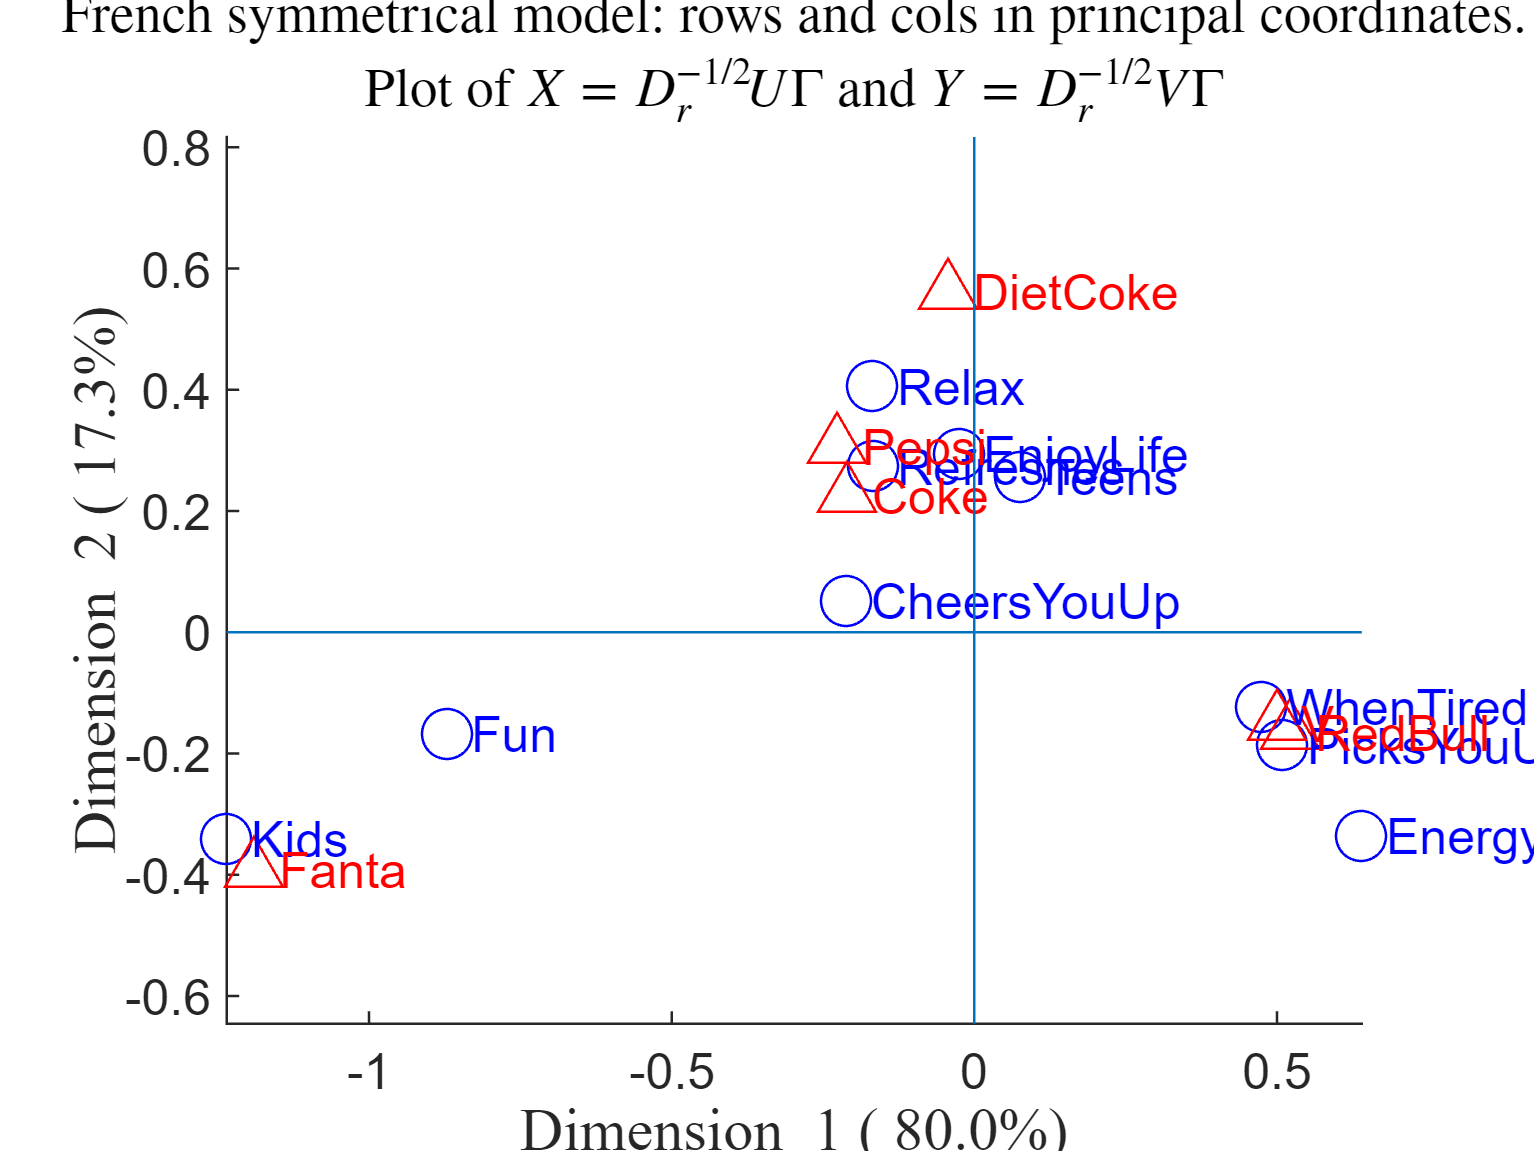

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1         0.55          0.31          0.80            0.80   
    dim_2         0.26          0.07          0.17            0.97   
    dim_3         0.10          0.01          0.03            1.00   
    dim_4         0.02          0.00          0.00            1.00   
    dim_5         0.02          0.00          0.00            1.00   

ROW POINTS
Results for dimension: 1
                   Scores    CntrbPnt2In    CntrbDim2In
                   ______    ___________    ___________

    Teens      


%l'indice di Cramer ci dice che l'associazione tra le due variabili della
%tabella è pari al 27.67 per cento del valore massimo posssibile.

% 5) Costruire e commentare il grafico di analisi delle corrispondenze.  
% Commentare la quota di inerzia spiegata e le relazioni tra i punti riga ed i punti colonna. 
% 

%% Analisi delle corrispondenze
outCA=CorAna(N,'Lr',labels(1:I,1),'Lc',labels(1:J,2));




%% Mostro la tabella che contiene i dettagli dell'inerzia spiegata
disp(outCA.Summary)

             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1         0.55          0.31          0.80            0.80   
    dim_2         0.26          0.07          0.17            0.97   
    dim_3         0.10          0.01          0.03            1.00   
    dim_4         0.02          0.00          0.00            1.00   
    dim_5         0.02          0.00          0.00            1.00   



% Con le prime due dimensioni latenti arriviamo a spiegare il 97,3% di
% variabilità (inerzia) della tabella di contingenza. Ottima riduzione
% delle dimensioni.
% Il grafico di analisi delle corrispondenze presenta una rappresentazione
% 2D molto accurata della posizione dei punti nello spazio originario a (I-1) e (J-1)
% dimensioni.
%
% Commento: 
% Ci 3 "gruppi" ben precisi: 
% 1) il brand "Fanta" è associato alle parole Kids e Fun (bambini e
% divertimento)
% 2) I marchi "Diet Coke", "Pepsi" e "Coke" sono associati prevalentemente alle
% parole Relax, Enjoy Life, Teens e Cheers you Up
% I marchi "V" e "Red Bull" sono associati alle parole "When Tired", "Picks you
% up" e "Energy".
% L'angolo tra il gruppo Coke/Pepsi e Redbull è vicino a 90 gradi==>
% assenza di relazione.
% L'angolo tra il gruppo Coke/Pepsi e Fanta è vicino a 90 gradi==>
% assenza di relazione.
% L'angolo tra Red Bull/V e Fanta è circa 180 gradi ==> forte relazione
% inversa. I marchi Red Bull e V sono considerati per adulti. Il marchio Fanta è
% associato ai bambini.
% La prima dimensione latente quindi è legata in qualche modo all'età, da
% adolescenti ad adulti passando da sinistra destra.
% 
% Nella seconda dimensione latente "andando dal basso verso l'alto 
% si può notare come si passa da bevande ad alto contenuto energetico e di zuccheri a una
% 'diet coke' con assenza di zuccheri". 
%
% 
% Il punto più vicino all'origine è CheersYouUp che dovrebbe, 
% indipendentemente dall'età, essere il motivo principale per cui si beve una
% soft drink (interpretazione ad libitum)
%  

% 6) Discutere i due punti riga più dominanti nella spiegazione
% dell'inerzia della prima dimensione latente.

% I punti riga dominanti che spiegano maggiormente l'inerzia della prima dimensione
% latente sono le parole Kids (42%) e i Fun (20%).
disp('Mostro in ordine crescente il contributo dei punti riga')

Mostro in ordine crescente il contributo dei punti riga


disp('alla spiegazione dell''inerzia della prima dimensione latente')

alla spiegazione dell'inerzia della prima dimensione latente


disp(sortrows(outCA.OverviewRows(:,'CntrbPnt2In_1')))

                   CntrbPnt2In_1
                   _____________

    EnjoyLife          0.00     
    Relax              0.00     
    Teens              0.00     
    Refreshes          0.01     
    CheersYouUp        0.01     
    WhenTired          0.07     
    PicksYouUp         0.11     
    Energy             0.16     
    Fun                0.20     
    Kids               0.42     



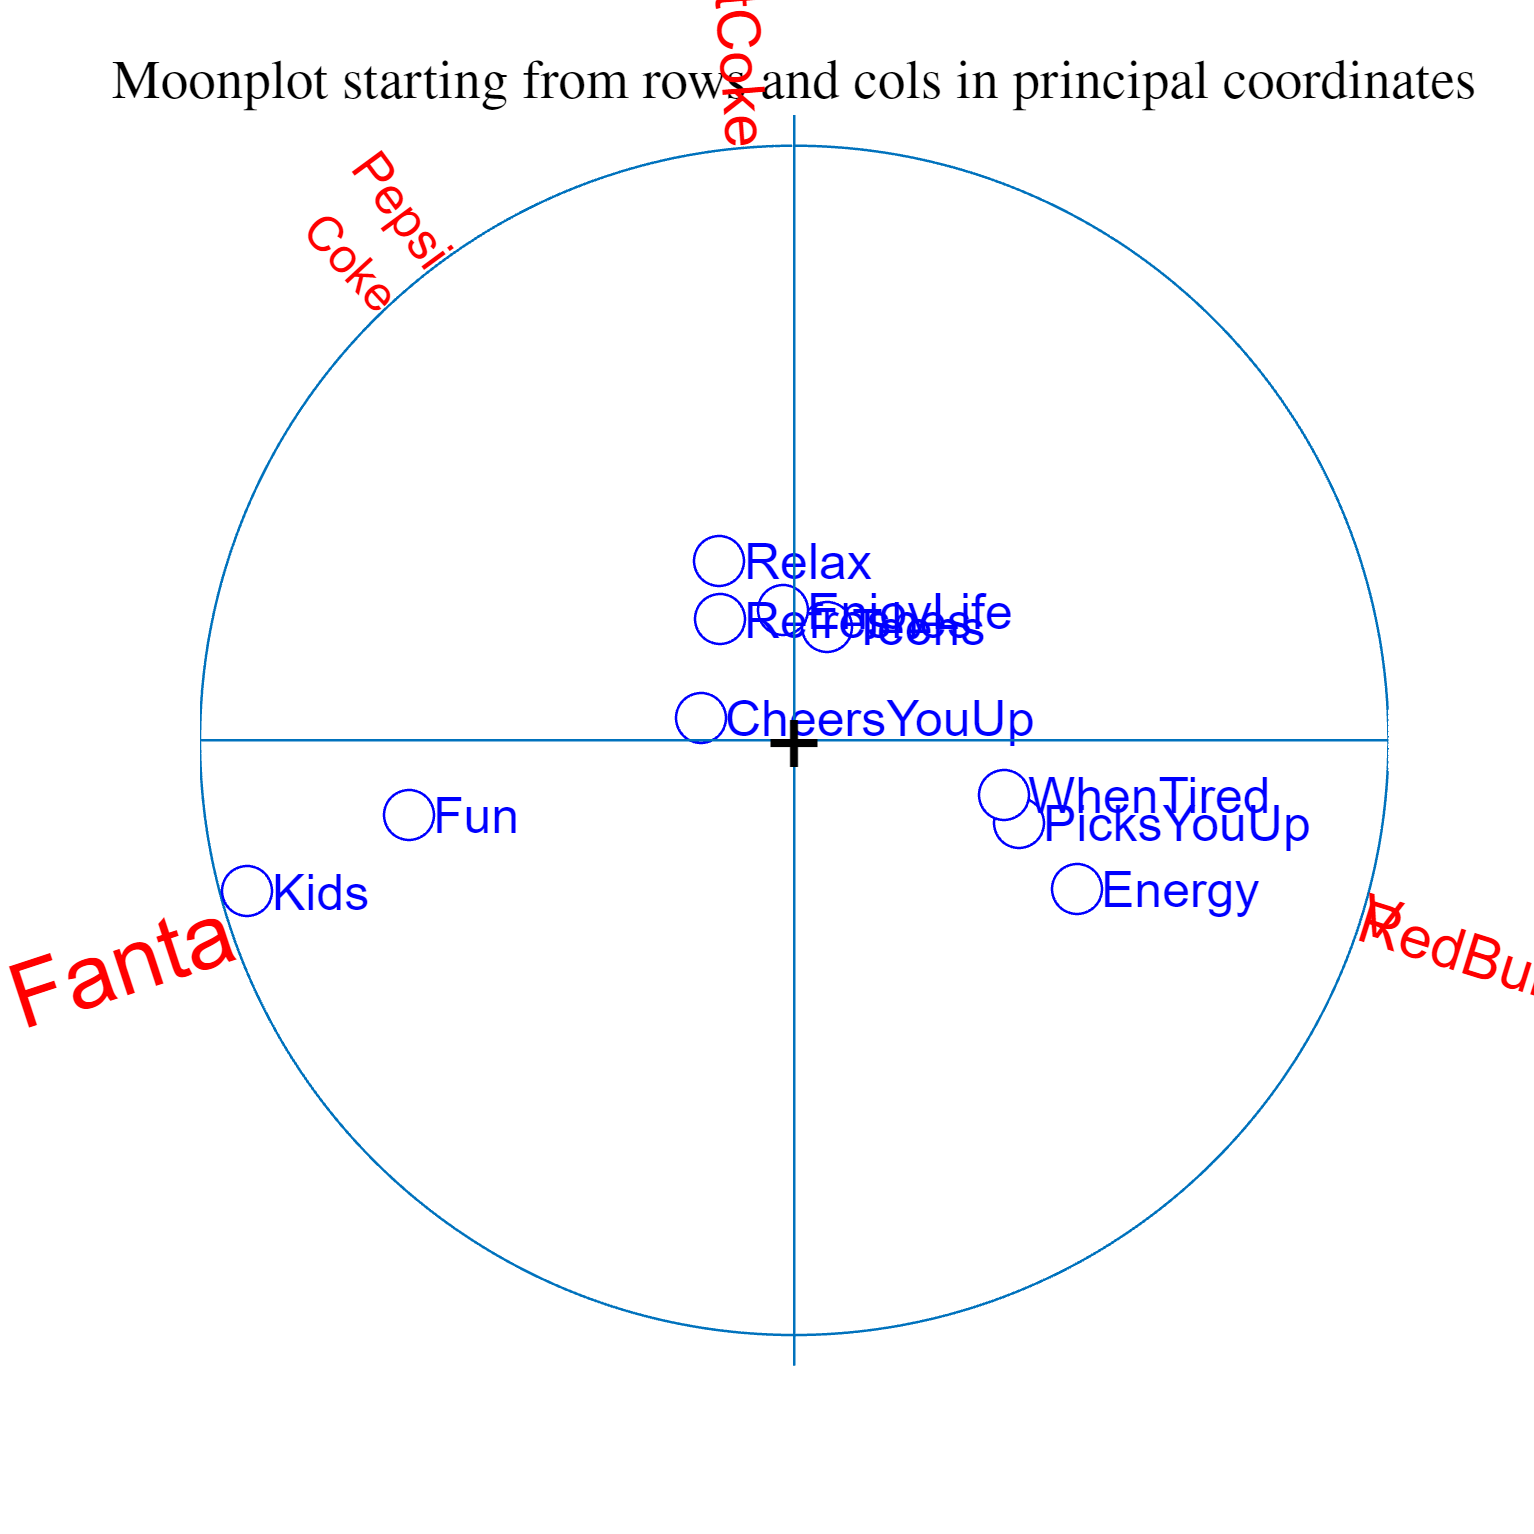


%
% 7) Costruire e commentare il moonplot

figure
moonplot(outCA)

--------------------------------
The colormap of the row labels is proportional to Mass


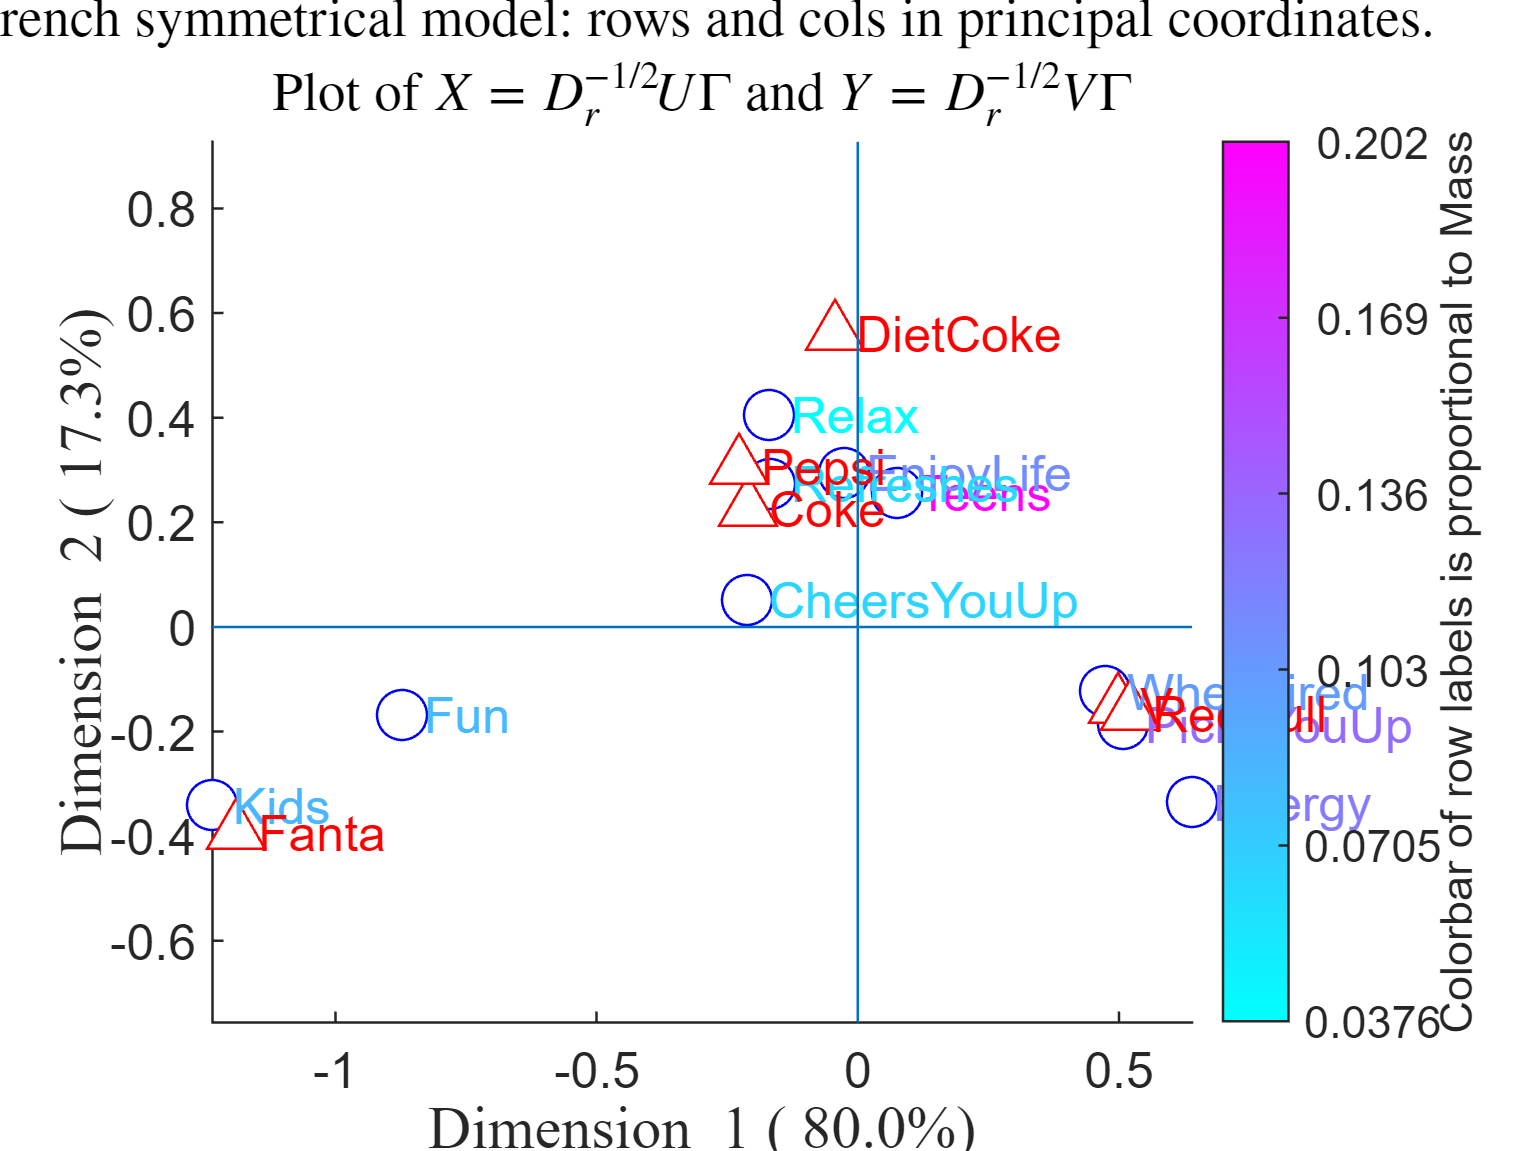

% Il moonplot ribadisce che l'angolo tra il vettore associato al punto
% colonna Fanta forma un angolo molto piccolo con i due vettori associati
% ai punti riga Kids e Fun
% Similmente il moonplot ribadisce che V e RedBull si trovano nella stessa
% direzione


% Colormap dei punti riga proporzionale alle masse di riga
figure
plots=struct;
plots.ColorMapLabelRows='Mass';
CorAnaplot(outCA,'plots',plots)

% Commento: Teens PicksYouUp and Energy sono i punti riga con le masse più
% grandi


% Colormap dei punti riga proporzionale al contributo dei punti riga
% alla spiegazione dell'inerzia delle prime due dimensioni latenti
% Dall'help della funzione CorAnaplot
%
%                   plots.ColorMapLabelRows='CntrbPnt2In' it is possible
%                   to have a colormap where row labels are proportional to
%                   the contribution of the row points to the inertia of
%                   the two latent dimensions.
plots=struct;
plots.ColorMapLabelRows='CntrbPnt2In';
CorAnaplot(outCA,'plots',plots)

--------------------------------
The colormap of the row labels is proportional to the contribution
of the row points to the inertia of the two latent dimensions


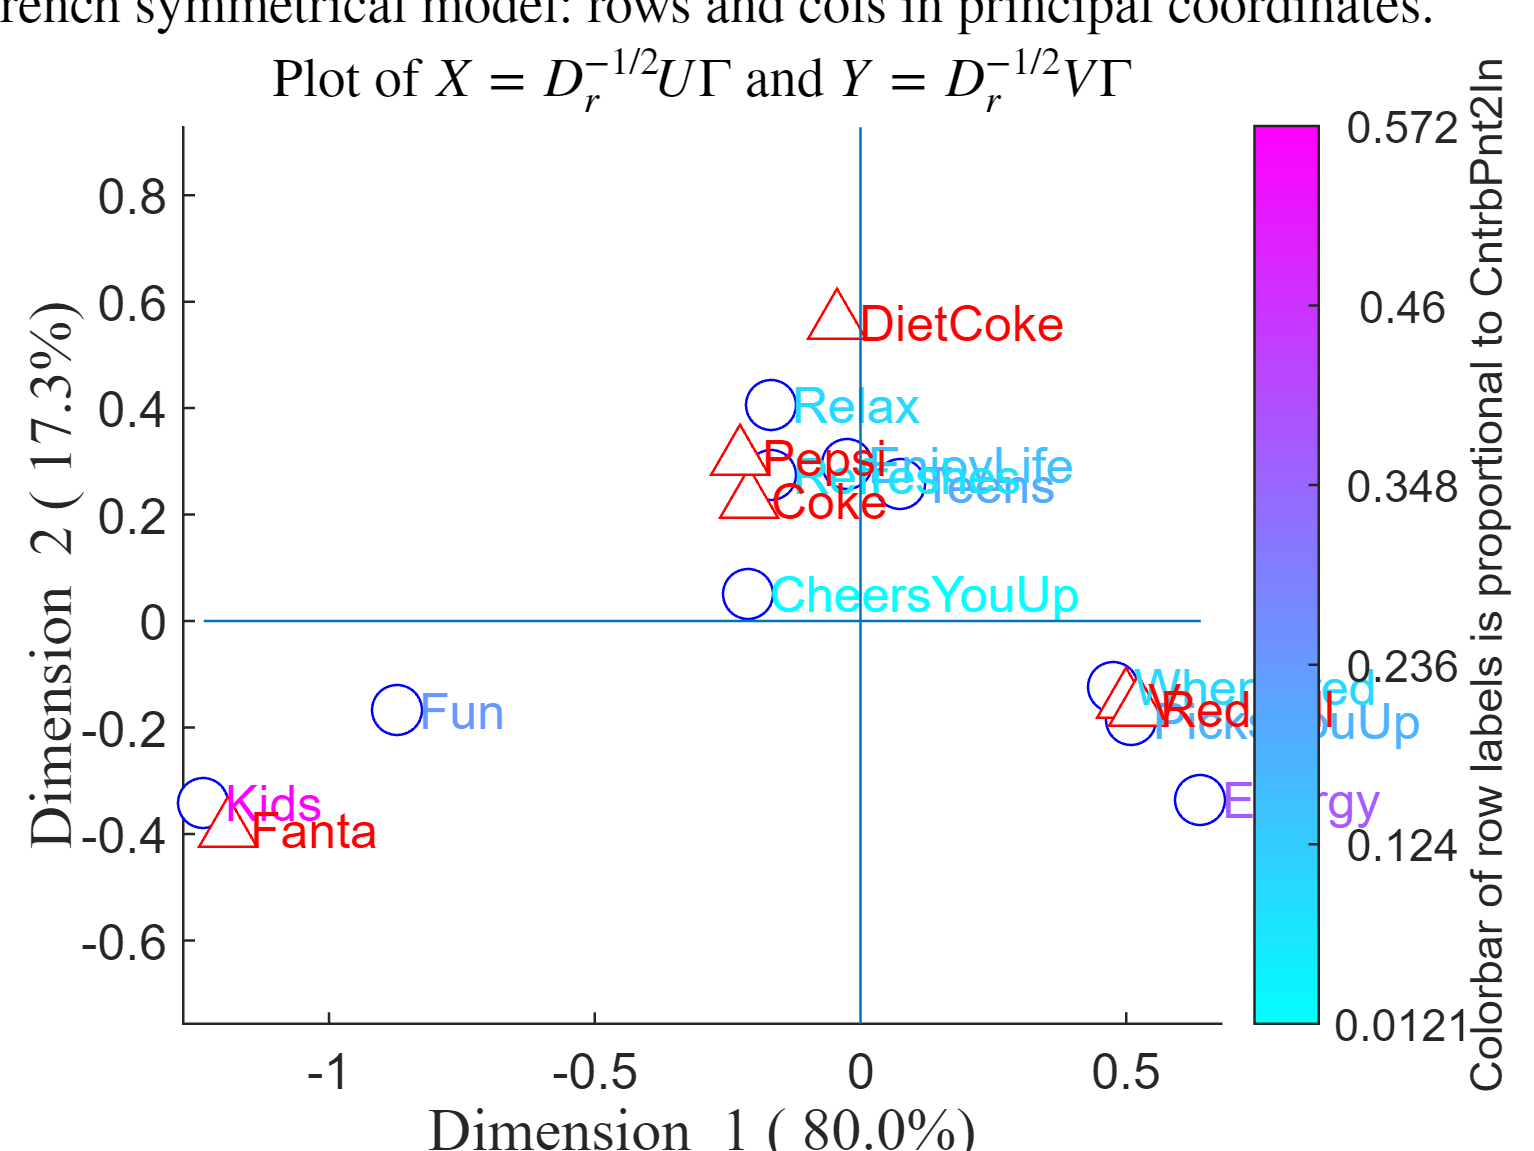

axis equal

% Contributo dei punti riga all'inerzia delle prime due dimensioni
CntrbPnt2In=sum(outCA.OverviewRows{:,["CntrbPnt2In_1"    "CntrbPnt2In_2"]},2);

% I due punti riga che danno il maggior contributo all'interza delle prime
% due dimensioni sono Kids e Energy
sortrows(array2table(CntrbPnt2In,"RowNames",rownam))

ans = 10×1 table
                   CntrbPnt2In
                   ___________

    CheersYouUp       0.01    
    Refreshes         0.08    
    WhenTired         0.10    
    Relax             0.10    
    EnjoyLife         0.15    
    PicksYouUp        0.18    
    Teens             0.21    
    Fun               0.24    
    Energy            0.37    
    Kids              0.57    
